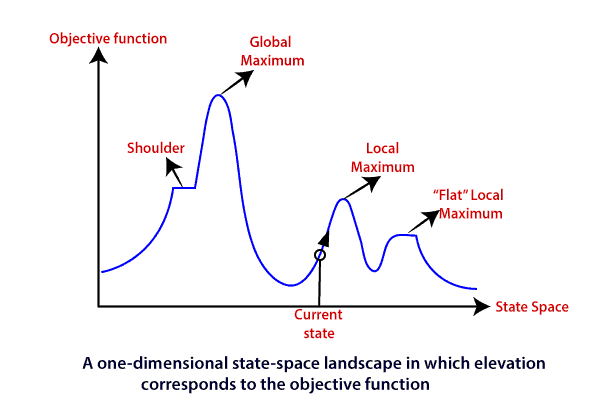

function main ()
    initial_solution = rand(1,3) * 10.24 - 5.12;
    step_size = 0.1;
    max_iteration = 1000;
    [best_solution, best_value] = hill_climbing_minimize(@rastrigin, initial_solution, step_size, max_iteration);

    disp('best solution:');
    disp(best_solution);
    disp('best value:');
    disp(best_value);
end

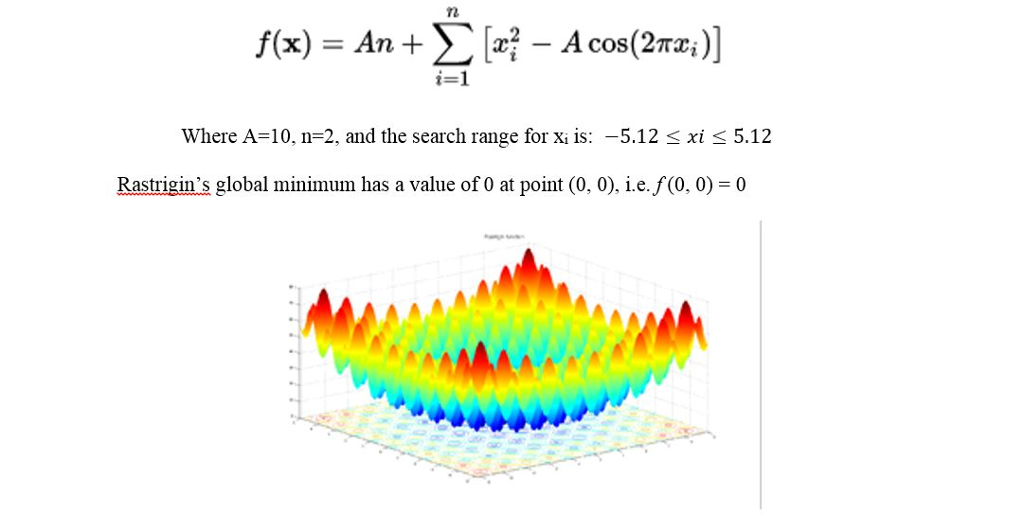

function value = rastrigin(x)
    % Rastrigin function
    A = 10;
    n = length(x);
    value = A * n;
    for i = 1:n
        value = value + (x(i)^2 - A * cos(2 * pi * x(i))); 
    end
end


function [best_solution, best_value] = hill_climbing_minimize(cost_function, initial_solution, step_size, max_iteration)
    current_solution = initial_solution;
    current_value = cost_function(initial_solution);
    for iter = 1:max_iteration
        new_solution = current_solution + step_size * randn(size(current_solution));
        new_value = cost_function(new_solution);
        if new_value < current_value
            current_solution = new_solution;
            current_value = new_value;
        end
    end
    best_solution = current_solution;
    best_value = current_value;
end